Purpose of this code is to test at various drug properties, setting thresholds of concentration for determining synergy measurements.

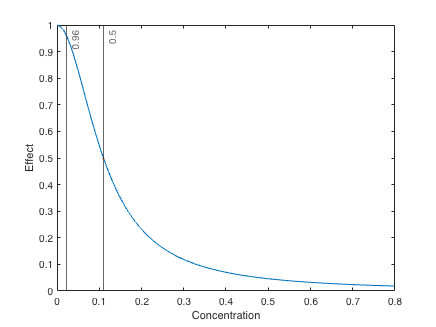

E0 = 1;
Emax = 0;
h = 2;
C = 0.11;
dmax = 0.8;

% calculate Hill equation
d = linspace(0, dmax, 100);
E = E0 + (Emax - E0) .* (d.^h ./ (C.^h + d.^h));

% calculate multiples of IC50
initial_d = 1;
low_d = 0.2* C;
high_d = 1* C;
low_E = E0 + (Emax - E0) .* (low_d.^h ./ (C.^h + low_d.^h));
high_E = E0 + (Emax - E0) .* (high_d.^h ./ (C.^h + high_d.^h));

% first plot (linear)
plot(d,E)
xline(low_d, '-', num2str(round(low_E, 2)))
xline(high_d, '-', num2str(round(high_E, 2)))
hold on
plot(C, 0.5*(E0-Emax), '.')
hold off
xlabel('Concentration')
ylabel('Effect')

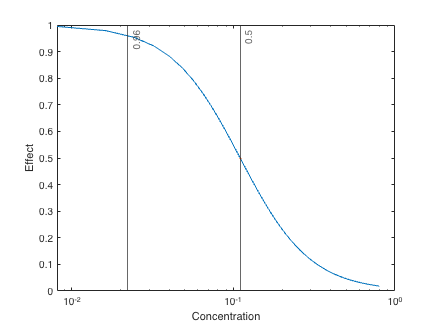


% second plot (log)
semilogx(d,E)
xline(low_d, '-', num2str(round(low_E, 2)))
xline(high_d, '-', num2str(round(high_E, 2)))
hold on
plot(C, 0.5*(E0-Emax), '.')
hold off
xlabel('Concentration')
ylabel('Effect')